# Gaussian Random Variables

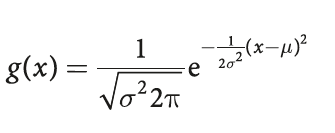

The 1-dimensional Gaussian function is described by the position of its peak μ and its width σ . The total area under the curve is unity and g(x) > 0, ∀x.

Note that the second argument to '***gaussfunc'***  is the variance not standard deviation. $V=\sigma^2$

clear
close all
clf

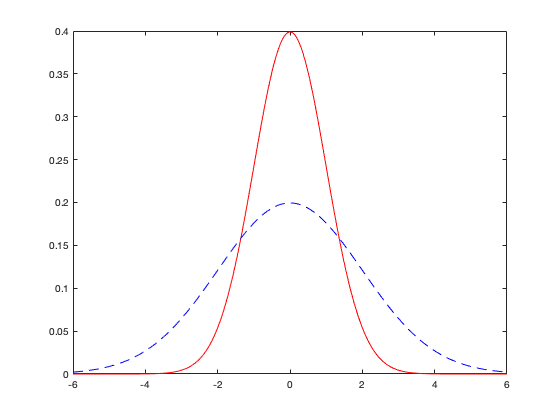

x = linspace(-6, 6, 500);
plot(x, gaussfunc(0, 1, x), 'r' ) % mean = 0 & Std_desv = 1
hold on
plot(x, gaussfunc(0, 2^2, x), '--b' )% mean = 0 & Std_desv = 2

The Gaussian can be extended to an arbitrary number of dimensions. The n-dimensional Gaussian, or multivariate normal distribution, is

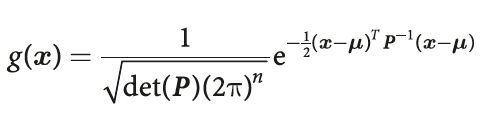

In this case  μ = (0, 0) and P = diag(1^2, 2^2) which

corresponds to uncorrelated variables with standard deviation of 1 and 2 respectively.

We can plot a 2-dimensional Gaussian:

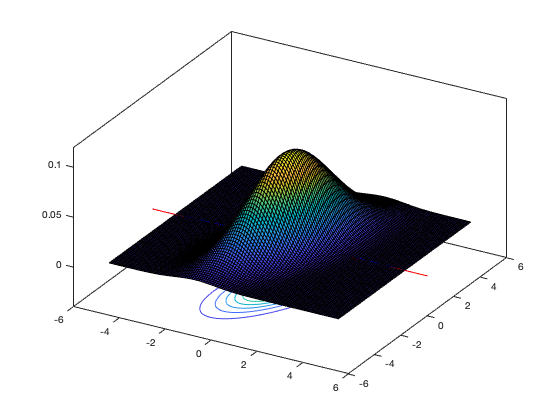

[x,y] = meshgrid(-5:0.1:5, -5:0.1:5);
P = [1 1;1 4];
surfc(x, y, gaussfunc([0 0], P, x, y))
axis([ -6 6 -6 6 -0.04 0.12])
view(30,40)